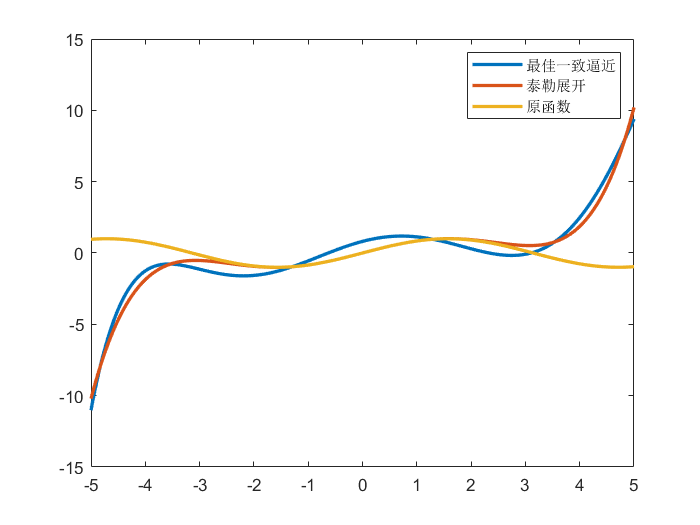

clc,clear,close all
syms x
f = sin(x);
n = 6;
a = -5;
b = 5;
p = consistent_approximation(f,a,b,n);




xx = a:0.01:b;
ff = subs(f,x,xx);
f11 = subs(p,x,xx);
f22 = subs(taylor(f,x,'Order',n+1),x,xx);
plot(xx,f11,'linewidth',2)
hold on
plot(xx,f22,'linewidth',2)
plot(xx,ff,'linewidth',2)
legend('最佳一致逼近','泰勒展开','原函数')